# **Approche modèle moyen - Commande d’un redresseur à absorption sinusoïdale**

**Projet CCSA1 2023/2024 : Douglas LIMA MILITÃO PINHEIRO**

## 1. Donnés numériques 

close all; clear; clc; 
E = 311 ; % [V] Amplitude de la source triphasé 
f = 50 ; % [Hz] fréquence de la source triphasé
w = 2*pi*f ; % [rad/s] pulsation de la source triphasé
r = 1 ; % [Ω] resistance interne de la source
L = 1e-3 ; % [H] inductance interne de la source
C = 4700e-6 ; % [F] capacité du côté dc
Rch= 100 ; % [Ω] resistance de charge du côté dc
Udc_cons = 600 ; % [V] consigne de tension du bus dc

### **1.1 Expliquer à quoi sert un PFC et quels sont les objectifs de commandes. ** 

Un PFC est une strategie/méthode utilisé pour améliorer le facteur de puissance d'un circuit en reduisant le taux de distorsion harmonique (THD), en ameliorant sa performance, dans ce cas un circuit redresseur. En cas d'utilisation sans être bien controllé, le circuit redresseur va générer de nombreux composants harmoniques de grande amplitude. En effet, les diodes ne conduisent que lorsque la tension des signaux AC est plus grande que la tension du condensateur du bus DC. Ainsi, à la fin, la courant vu par le reseaux AC sera des courbes avec grande amplitude et courte durée. C'est-à-dire, les courantes AC auront plein d'harmoniques, augmentant le taux de distorsion harmonique et réduisant le facteur de puissance, ce qui est mauvais pour le réseaux. La strategie d'impleméntation du PFC dans ce circuit redresseur est basée sur la méthode de commande.

## 2. Modèle moyen du système et transformation de Park

### 2.1. Bilan de puissance AC et DC

**Le circuit donne : **

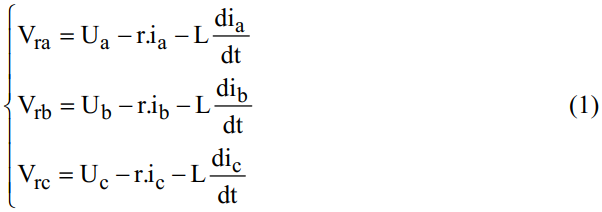

**Faire le bilan de puissance en AC et DC afin d’exprimer le courant de la capacité :**

    En faisant l'assumption que la puissance du bus AC est égal à la puissance du bus DC


$$P_{\textrm{ac}} =V_{\textrm{ra}} i_a +V_{\textrm{rb}} i_b +V_{\textrm{rc}} i_c =P_{\textrm{dc}} =\frac{U_{\textrm{dc}}^2 }{R_{\textrm{ch}} }+U_{\textrm{dc}} \left(C\frac{{\textrm{dU}}_{\textrm{dc}} }{\textrm{dt}}\right)\leftrightarrow C\frac{{\textrm{dU}}_{\textrm{dc}} }{\textrm{dt}}=\frac{1}{U_{\textrm{dc}} }\left(V_{\textrm{ra}} i_a +V_{\textrm{rb}} i_b +V_{\textrm{rc}} i_c \right)-\frac{U_{\textrm{dc}} }{R_{\textrm{ch}} }$$


### 2.2. Transformée Park

**Pour commander efficacement le PFC, les grandeurs triphasées abc sont projetées dans un repère orthogonal diphasé (repère d,q) tournant. Avec la transformée de Park en conservant l’amplitude des tensions et des courants, montrer que le modèle (1) et l’équation de courant dans le repère d, q s’écrivent :**

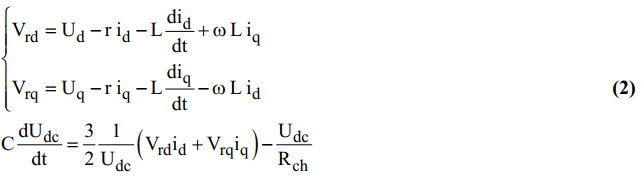

Les équations en (1) peuvent être reécrit comme :


$$\left\lbrack \begin{array}{c}
V_{\textrm{ra}} \\
V_{\textrm{rb}} \\
V_{\textrm{rc}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
U_a \\
U_b \\
U_c 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
r & 0 & 0\\
0 & r & 0\\
0 & 0 & r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
L & 0 & 0\\
0 & L & 0\\
0 & 0 & L
\end{array}\right\rbrack \frac{d}{\textrm{dt}}\left(\left\lbrack \begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right\rbrack \right)$$


Soit $\Gamma$ la matrice pour transposer au système au repère dq0 (transformée de Park)


$$\Gamma \left\lbrack \begin{array}{c}
V_{\textrm{ra}} \\
V_{\textrm{rb}} \\
V_{\textrm{rc}} 
\end{array}\right\rbrack =\Gamma \left\lbrack \begin{array}{c}
U_a \\
U_b \\
U_c 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
r & 0 & 0\\
0 & r & 0\\
0 & 0 & r
\end{array}\right\rbrack \Gamma \left\lbrack \begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
L & 0 & 0\\
0 & L & 0\\
0 & 0 & L
\end{array}\right\rbrack \Gamma \frac{d}{\textrm{dt}}\left(\Gamma^{-1} \Gamma \left\lbrack \begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right\rbrack \right)$$



$$\left\lbrack \begin{array}{c}
V_{\textrm{rd}} \\
V_{\textrm{rq}} \\
V_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
U_d \\
U_q \\
U_0 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
r & 0 & 0\\
0 & r & 0\\
0 & 0 & r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
L & 0 & 0\\
0 & L & 0\\
0 & 0 & L
\end{array}\right\rbrack \Gamma \frac{d}{\textrm{dt}}\left(\Gamma^{-1} \left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack \right)$$


Par définition $\frac{d}{\textrm{dt}}\left(\Gamma^{-1} \left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack \right)=\left(\frac{d\Gamma^{-1} }{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack +\Gamma^{-1} \frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack \right)$, donc :


$$\left\lbrack \begin{array}{c}
V_{\textrm{rd}} \\
V_{\textrm{rq}} \\
V_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
U_d \\
U_q \\
U_0 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
r & 0 & 0\\
0 & r & 0\\
0 & 0 & r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
L & 0 & 0\\
0 & L & 0\\
0 & 0 & L
\end{array}\right\rbrack \Gamma \left(\frac{d\Gamma^{-1} }{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack +\Gamma^{-1} \frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack \right)$$



$$\left\lbrack \begin{array}{c}
V_{\textrm{rd}} \\
V_{\textrm{rq}} \\
V_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
U_d \\
U_q \\
U_0 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
r & 0 & 0\\
0 & r & 0\\
0 & 0 & r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
L & 0 & 0\\
0 & L & 0\\
0 & 0 & L
\end{array}\right\rbrack \Gamma \frac{d\Gamma^{-1} }{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
L & 0 & 0\\
0 & L & 0\\
0 & 0 & L
\end{array}\right\rbrack \Gamma \Gamma^{-1} \frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack$$


Où $\Gamma \Gamma^{-1} =I$ et $\Gamma \frac{d\Gamma^{-1} }{\textrm{dt}}=\left\lbrack \begin{array}{ccc}
0 & -\omega \; & 0\\
\omega \; & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$


$$\left\lbrack \begin{array}{c}
V_{\textrm{rd}} \\
V_{\textrm{rq}} \\
V_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
U_d \\
U_q \\
U_0 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
r & 0 & 0\\
0 & r & 0\\
0 & 0 & r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
L & 0 & 0\\
0 & L & 0\\
0 & 0 & L
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
0 & -\omega \; & 0\\
\omega \; & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
L & 0 & 0\\
0 & L & 0\\
0 & 0 & L
\end{array}\right\rbrack \frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q \\
i_0 
\end{array}\right\rbrack$$


On considère que la composant homopolaire est toujours nulle, parce que le système est purement alternatif :


$$\left\lbrack \begin{array}{c}
V_{\textrm{rd}} \\
V_{\textrm{rq}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
U_d \\
U_q 
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
r & 0\\
0 & r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & L\omega \;\\
-L\omega  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
L & 0\\
0 & L
\end{array}\right\rbrack \frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack$$


Comme les composantes de tension et courant sont maintenu avec les mêmes amplitudes, la puissance maximale est décrit :


$$\begin{array}{l}
P_{\textrm{ab}} =\left(V_{\textrm{ra}} i_a +V_{\textrm{rb}} i_b +V_{\textrm{rc}} i_c \right)=\frac{3}{2}\textrm{VI}\\
P_{\textrm{dq}} =\left(V_{\textrm{rd}} i_d +V_{\textrm{rq}} i_q \right)=\textrm{VI}
\end{array}\to P_{\textrm{abc}} =\frac{3}{2}P_{\textrm{dq}}$$


Donc on arrive au modèle (2), écrit comme :


$$\left\lbrack \begin{array}{c}
V_{\textrm{rd}} \\
V_{\textrm{rq}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
U_d \\
U_q 
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
r & 0\\
0 & r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & L\omega \;\\
-L\omega  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
L & 0\\
0 & L
\end{array}\right\rbrack \frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack$$



$$C\frac{{\textrm{dU}}_{\textrm{dc}} }{\textrm{dt}}=\frac{1}{U_{\textrm{dc}} }\frac{3}{2}\left(V_{\textrm{rd}} i_d +V_{\textrm{rq}} i_q \right)-\frac{U_{\textrm{dc}} }{R_{\textrm{ch}} }$$


### **2.3. Valeurs de Ud et Uq**

**A partir des trois tensions triphasées Ua, Ub et Uc, ****déterminer**** la valeur de Ud et Uq à l’aide d’****un schéma Simulink****. L’angle de la transformée de Park est ****synchronisé avec la valeur maximale de**** Ua.**

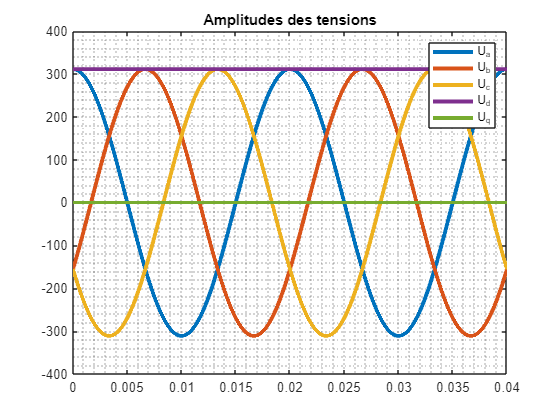

Amplitude_Ud_Uq_results = sim("Amplitude_Ud_Uq.slx");

figure
plot(Amplitude_Ud_Uq_results.t, [Amplitude_Ud_Uq_results.Uabc Amplitude_Ud_Uq_results.Udq0(:,1:2)],LineWidth=3)
grid minor
legend("U_a","U_b","U_c","U_d","U_q")
title("Amplitudes des tensions")

Les amplitudes sont conservées :

Ud = E;
Uq = 0;

## **3. Analyse du système dans le repère d-q**

### 3.1. Quelle est la nature du système d’équation (2) ?

Il est un système non-lineaire à variables couplées. La non-linearité est liée à la variable $U_{\textrm{dc}}$ qui est élevé a puissance -1 en multipliant des autres variables ($I_d$ et $I_q$) du système.

 
$$C\frac{{\textrm{dU}}_{\textrm{dc}} }{\textrm{dt}}=\frac{3}{2}\left(V_{\textrm{rd}} i_d +V_{\textrm{rq}} i_q \right)\;{\mathit{\mathbf{U}}}_{\textrm{dc}}^{-1} -\frac{U_{\textrm{dc}} }{R_{\textrm{ch}} }$$


### **3.2. **Donner l’expression de Gv et sa valeur numérique. 

**Pour simplifier le problème de commande, on approxime le terme **$\frac{1}{U_{\textrm{dc}} }\left(V_{\textrm{rd}} i_d +V_{\textrm{rq}} i_q \right)$** par **$\frac{E}{U_{\textrm{dc}}^# }i_d$** dans (2) ou **$U_{\textrm{dc}}^#$** est la consigne de tension du bus continu. Ce qui donne : **


$$C\frac{{\textrm{dU}}_{\textrm{dc}} }{\textrm{dt}}=\frac{3}{2}\frac{E}{U_{\textrm{dc}}^# }i_d -\frac{U_{\textrm{dc}} }{R_{\textrm{ch}} }$$


 
$$CU_{\textrm{dc}} \left(p\right)p=\frac{3}{2}\frac{E}{U_{\textrm{dc}}^# }i_d \left(p\right)-\frac{1}{R_{\textrm{ch}} }U_{\textrm{dc}} \left(p\right)$$



$$CU_{\textrm{dc}} \left(p\right)p+\frac{1}{R_{\textrm{ch}} }U_{\textrm{dc}} \left(p\right)=\frac{3}{2}\frac{E}{U_{\textrm{dc}}^# }i_d \left(p\right)$$



$$U_{\textrm{dc}} \left(p\right)\left(\textrm{Cp}+\frac{1}{R_{\textrm{ch}} }\right)=\frac{3}{2}\frac{E}{U_{\textrm{dc}}^# }i_d \left(p\right)$$



$$\frac{U_{\textrm{dc}} \left(p\right)}{i_d \left(p\right)}=\frac{3}{2}\frac{E}{U_{\textrm{dc}}^# }\frac{1}{\left(\textrm{Cp}+\frac{1}{R_{\textrm{ch}} }\right)}=\frac{3}{2}\frac{E}{U_{\textrm{dc}}^# }R_{\textrm{ch}} \frac{1}{\left(R_{\textrm{ch}} \textrm{Cp}+1\right)}=\frac{G_v }{\left(R_{\textrm{ch}} \textrm{Cp}+1\right)}$$


où $G_v =\frac{3}{2}\frac{E}{U_{\textrm{dc}}^# }R_{\textrm{ch}}$

Gv = (3/2)*E*Rch/Udc_cons

Gv = 77.7500

### **3.3. L'ordre de grandeur des dynamiques**

**Donner l’ordre de grandeur de la dynamique des courants et de la tension Udc en boucle ouverte. Quelle structure de commande qu’on peut envisager ? Justifier votre réponse.**

Pour le boucle de la tension Udc

tau_udc = Rch*C

tau_udc = 0.4700

Pour les boucles de courant Id et Iq


$$V_{\textrm{rd},\;\textrm{rq}} =U_{d,\;q} -ri_{d,\;q} -L\;\frac{di_{d,\;q} }{\textrm{dt}}\pm \omega Li_{q,\;d} \leftrightarrow ri_{d,\;q} +L\;\frac{di_{d,\;q} }{\textrm{dt}}=U_{d,\;q} -V_{\textrm{rd},\;\textrm{rq}} \pm \omega Li_{q,\;d} =U_{d,\;q}^*$$



$$i_{d,\;q} \left(p\right)\left(r+\textrm{Lp}\right)=U_{d,\;q}^* \left(p\right)$$



$$\frac{i_{d,\;q} \left(p\right)\;}{U_{d,\;q}^* \left(p\right)}=\frac{\frac{1}{r}}{\left(\frac{L}{r}p+1\right)}$$


Où $U_{d,\;q}^* =U_{d,\;q} -V_{\textrm{rd},\;\textrm{rq}} \pm \omega Li_{q,\;d}$ sont des commandes fictives à être fait un feedfoward. Donc, la constante de temp est :

tau_id_iq = L/r

tau_id_iq = 1.0000e-03

Les boucles des courants ont des constantes de temp beaucoup plus rapide que la boucle de tension. On a donc deux possibilités envisagés: 

- Boucles imbriquées - la boucle de tension génère le consigne des boucles de courant internes. Les boucles de courant ont des constantes de temp plus faibles que la boucle de tension. Un feedfoward est utilisé pour decoupler les variables.

- Retour d'état -  tous les variables sont maîtrisées via retour d'état.

### **3.3. Déterminer la valeur de courant **$i_d$ **en régime établi **$\left(i_{\textrm{de}} \right)$** pour de **$U_{\textrm{dc}} =U_{\textrm{dc}}^#$**.**

En supposant que l'entrée est un échelon d'amplitude $i_{\textrm{de}}$ :


$$U_{\textrm{dc}} \left(p\right)=\frac{i_{\textrm{de}} }{p}\frac{G_v }{\left(R_{\textrm{ch}} \textrm{Cp}+1\right)}$$


Selon le théorème de la valeur finale :


$$\lim_{t\to \propto\;} \;U_{\textrm{dc}} \;\left(t\right)=U_{\textrm{dc}}^# =\lim_{p\to 0} \;pU_{\textrm{dc}} \;\left(p\right)=p\frac{i_{\textrm{de}} }{p}\frac{G_v }{\left(R_{\textrm{ch}} \textrm{Cp}+1\right)}\leftrightarrow U_{\textrm{dc}}^# =i_{\textrm{de}} G_v \to i_{\textrm{de}} =\frac{U_{\textrm{dc}}^# }{G_v }$$


i_de = Udc_cons/Gv

i_de = 7.7170

## **4. Approche fréquentielle**

### **4.1. Commande des courants **id **, **iq

#### 4.1.1. Consigne $i_q^#$

**On cherche d’abord à commander les deux courants **$i_d ,i_q$ **avec **$i_d^# =i_{\textrm{de}}$**. Comment choisir la consigne **$i_q^#$** ?**

Dans la section 3, une simplification a été fait pour la commande de $U_{\textrm{dc}}$, le terme lié à $i_q$ est negligée. C'est-à-dire que $i_q$ ne sera pas utilisé pour contrôler $U_{\textrm{dc}}$ seulement $i_d$, donc sa consigne est prise toujours égale à 0, parce que quelque soit sa alteration, elle sera consideré comme une perturbation au système (par rapport à $U_{\textrm{dc}}$).

#### 4.1.2. Cahier des charges et placement des pôles

- **Nous désirons un temps de réponse à 5% de 12 ms sans erreur statique.**

- **Pour une implémentation numérique, la période d’échantillonnage est choisie à 0,2 ms.**

Te = 0.2e-3;
tau_bf = (12e-3)/3; % approximation utilisé pour trouver la constant de temp d'un système de premier ordre
pole_bf_courant_z = pole(c2d(tf(1,[tau_bf 1]),Te,'zoh')); % pole discret souhaitée en boucle fermée

Le systeme discretisé :

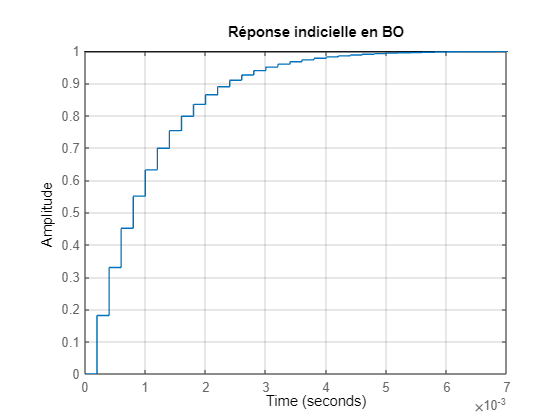

H_courant_z = c2d(tf(1/r,[L/r 1]),Te,'zoh');
figure
hold on
step(H_courant_z);
grid minor
title("Réponse indicielle en BO")
hold off

[num_H_courant_z, den_H_courant_z] = tfdata(H_courant_z,'v');

**Calcul des paramètres du PI discret**

r0_courant = (1 - pole_bf_courant_z)/num_H_courant_z(2);
r1_courant = r0_courant*den_H_courant_z(2);
K_PI = tf([r0_courant r1_courant],[1 -1],Te,'Variable','z^-1')

K_PI =
 
  0.2691 - 0.2203 z^-1
  --------------------
        1 - z^-1
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


**Vérification des paramètres du correcteur**

H_test_bf_courant = minreal(feedback(K_PI*H_courant_z,1))

H_test_bf_courant =
 
   0.04877 z^-1
  ---------------
  1 - 0.9512 z^-1
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


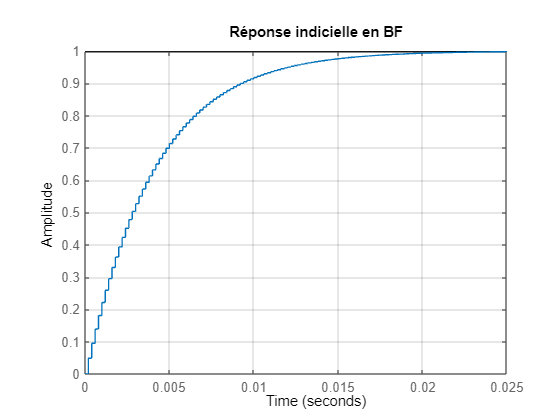

figure
hold on
step(H_test_bf_courant);
grid MINOR
title("Réponse indicielle en BF")

step2 = stepinfo(H_test_bf_courant,'RiseTimeThreshold',[0 0.95]); % Calcul le temp de reponse a 5%
step2.RiseTime

ans = 0.0118

Le correcteur est bien parametré pour le modèle discret.

#### 4.1.3. Tester les correcteurs de courant sur Matlab/Simulink avec le modèle moyen d-q (*pfc_dq_2019.slx*). Vérifier le respect du cahier des charges.

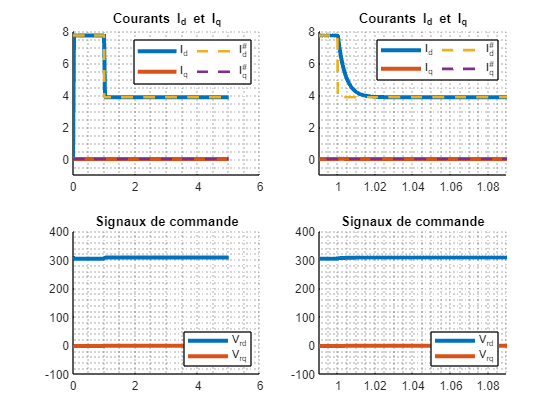

Control_Udc = 0; R_K_PIDf = 1; S_K_PIDf = 1; %desactive le controle de Udc dans le fichier de simulation
temp_simu = 5; id_sat = 0;
PFC_dq_2019_frequentielle_results = sim("PFC_dq_2019_frequentielle.slx");

figure
subplot(221)
hold on
plot(PFC_dq_2019_frequentielle_results.t, [PFC_dq_2019_frequentielle_results.Id, PFC_dq_2019_frequentielle_results.Iq],LineWidth=3)
plot(PFC_dq_2019_frequentielle_results.t, [PFC_dq_2019_frequentielle_results.Id_cons, PFC_dq_2019_frequentielle_results.Iq_cons],'--',LineWidth=2)
grid minor
legend("I_d","I_q","I_d^#","I_q^#",'NumColumns',2)
ylim([-1 8])
title("Courants I_d et I_q")

subplot(223)
hold on
plot(PFC_dq_2019_frequentielle_results.t, [PFC_dq_2019_frequentielle_results.Vrd PFC_dq_2019_frequentielle_results.Vrq],LineWidth=3)
grid minor
legend("V_{rd}","V_{rq}",'Location','southeast')
title("Signaux de commande")
ylim([-100 400])

subplot(222)
hold on
plot(PFC_dq_2019_frequentielle_results.t, [PFC_dq_2019_frequentielle_results.Id, PFC_dq_2019_frequentielle_results.Iq],LineWidth=3)
plot(PFC_dq_2019_frequentielle_results.t, [PFC_dq_2019_frequentielle_results.Id_cons, PFC_dq_2019_frequentielle_results.Iq_cons],'--',LineWidth=2)
grid minor
legend("I_d","I_q","I_d^#","I_q^#",'NumColumns',2)
title("Courants I_d et I_q")
xlim([0.99 1.09])
ylim([-1 8])

subplot(224)
hold on
plot(PFC_dq_2019_frequentielle_results.t, [PFC_dq_2019_frequentielle_results.Vrd PFC_dq_2019_frequentielle_results.Vrq],LineWidth=3)
grid minor
legend("V_{rd}","V_{rq}",'Location','southeast')
title("Signaux de commande")
xlim([0.99 1.09])
ylim([-100 400])

La figure montre que les deux courants sont bien maîtrises par le correcteur et la réponse est comme souhaitée initiallement.

### **4.2. Commande de la tension de sortie Udc**

- Cahier des charges :

w_0v = 50;
qsi_0v = 3;

H_udc_bf_z = c2d(tf(w_0v^2,[1 2*qsi_0v*w_0v w_0v^2]),Te);
H_udc_bf_z.Variable = 'z^-1'

H_udc_bf_z =
 
  4.901e-05 z^-1 + 4.804e-05 z^-2
  -------------------------------
   1 - 1.942 z^-1 + 0.9418 z^-2
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


- Fonction transfert du système :

H_udc_z = c2d(tf(Gv*1,conv([tau_bf 1],[Rch*C 1])),Te,'zoh'); % produit entre les deux systèmes
H_udc_z.Variable = 'z^-1'

H_udc_z =
 
  0.0008134 z^-1 + 0.0007998 z^-2
  -------------------------------
   1 - 1.951 z^-1 + 0.9508 z^-2
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


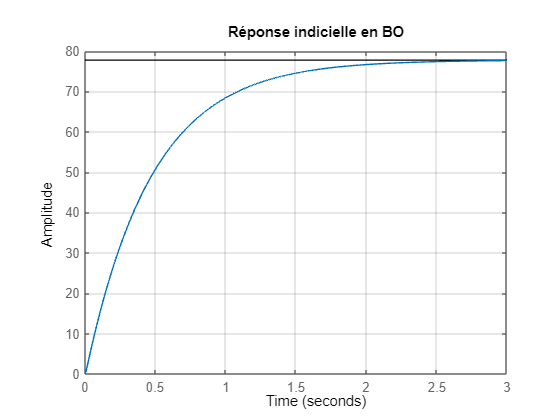

figure
hold on
step(H_udc_z);
grid MINOR
title("Réponse indicielle en BO")

**Calcul des paramètres du PID filtré discret**

[~, den_H_udc_bf_z] = tfdata(H_udc_bf_z,'v');
[num_H_udc_z, den_H_udc_z] = tfdata(H_udc_z,'v');

r0_udc = (1+den_H_udc_bf_z(2)+den_H_udc_bf_z(3))/(num_H_udc_z(2)+num_H_udc_z(3));
r1_udc = den_H_udc_z(2)*r0_udc;
r2_udc = den_H_udc_z(3)*r0_udc;
s1_udc = r0_udc*num_H_udc_z(3) - den_H_udc_bf_z(3);
K_PIDf = tf([r0_udc r1_udc r2_udc],conv([1 -1],[1 s1_udc]),Te,'Variable','z^-1');

H_test_bf_udc = minreal(feedback(K_PIDf*H_udc_z,1),1e-5)

H_test_bf_udc =
 
  4.894e-05 z^-1 + 4.812e-05 z^-2
  -------------------------------
   1 - 1.942 z^-1 + 0.9418 z^-2
 
Sample time: 0.0002 seconds
Discrete-time transfer function.
Model Properties


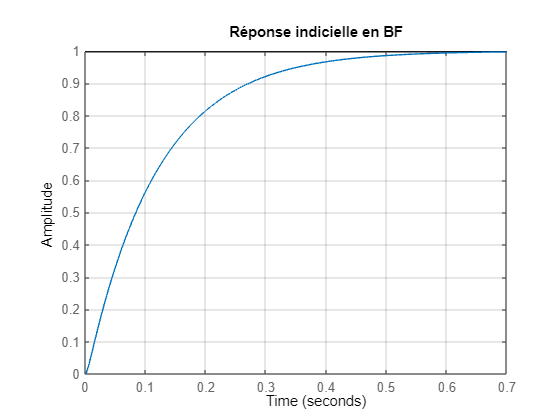

figure
hold on
step(H_test_bf_udc);
grid MINOR
title("Réponse indicielle en BF")

pole(H_udc_bf_z)

ans =     0.9983
    0.9434


pole(H_test_bf_udc)

ans =     0.9983
    0.9434


Les poles en boucle fermée sont égales aux pôles du modèle souhaitée, donc le correcteur est bien parametré pour le modèle discret.

#### **4.2.3. Mettre en place une anti-saturation pour ne pas dépasser les limites de la commande.**

Pour mettre en oeuvre l'anti-saturation du correcteur PID filtré, le correcteur sera implementé dans la structure suivant :

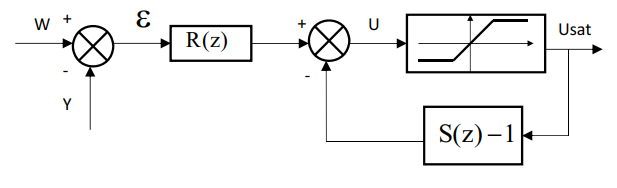

Où R(z) et S(z) sont respectivement les zéros et pôles du correcteur. L'équations décrivent ce système comme :


$$u\left(z\right)=R\left(z\right)e\left(z\right)-\left(S\left(z\right)-1\right)u_{\textrm{sat}} \left(z\right),\textrm{où}\;u_{\textrm{sat}} =\textrm{sat}\left(u\right)$$


C'est-à-dire donc, que si on travaille dans la zone lineaire (non-saturée), $u_{\textrm{sat}} =u$ donc :


$$u\left(z\right)=R\left(z\right)e\left(z\right)-\left(S\left(z\right)-1\right)u\left(z\right)\to \frac{u\left(z\right)}{e\left(z\right)}=\frac{R\left(z\right)}{S\left(z\right)}$$


Le correcteur n'est pas affecté et fonctionnera comme initiallement projeté. Par contre, si on travaille dans la zone non-lineaire :


$$u\left(z\right)=R\left(z\right)e\left(z\right)-\left(S\left(z\right)-1\right)u_{\textrm{sat}} \left(z\right)$$


[R_K_PIDf,S_K_PIDf] = tfdata(K_PIDf,'v');
id_sat = 40;

#### 4.2.4. Tester le correcteur de tension sur Matlab/Simulink avec le modèle moyen d-q pour la consigne de $U_{\textrm{dc}}^# =600V$. Vérifier le respect du cahier des charges.

#### 4.2.5. Vérifier le bon fonctionnement de l’ensembles des correcteurs et tester la robustesse vis-à-vis d’une variation brusque de la charge $R_{\textrm{ch}}$ de$100\Omega \;$ à $50\Omega$.  

La variation de la charge est appliquée en t égale à 2.5s. 

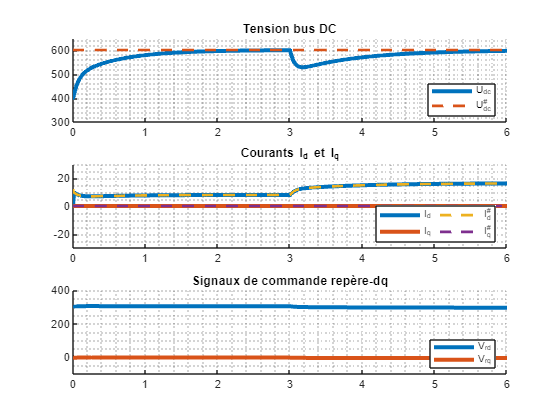

Control_Udc = 1; %active le controle de Udc dans le fichier de simulation
temp_simu = 8;
PFC_dq_2019_frequentielle_results_2 = sim("PFC_dq_2019_frequentielle.slx");

figure
subplot(311)
hold on
plot(PFC_dq_2019_frequentielle_results_2.t, [PFC_dq_2019_frequentielle_results_2.Udc],LineWidth=3)
plot(PFC_dq_2019_frequentielle_results_2.t, PFC_dq_2019_frequentielle_results_2.Udc_cons,'--',LineWidth=2)
ylim([300 650])
xlim([0 6])
grid minor
legend("U_{dc}","U_{dc}^#",'Location','southeast')
title("Tension bus DC")

subplot(312)
hold on
plot(PFC_dq_2019_frequentielle_results_2.t, [PFC_dq_2019_frequentielle_results_2.Id, PFC_dq_2019_frequentielle_results_2.Iq],LineWidth=3)
plot(PFC_dq_2019_frequentielle_results_2.t, [PFC_dq_2019_frequentielle_results_2.Id_cons, PFC_dq_2019_frequentielle_results_2.Iq_cons],'--',LineWidth=2)
xlim([0 6])
ylim([-30 30])
grid minor
legend("I_d","I_q","I_d^#","I_q^#",'NumColumns',2,'Location','southeast')
title("Courants I_d et I_q")

subplot(313)
hold on
plot(PFC_dq_2019_frequentielle_results_2.t, [PFC_dq_2019_frequentielle_results_2.Vrd PFC_dq_2019_frequentielle_results_2.Vrq],LineWidth=3)
grid minor
ylim([-100 400])
xlim([0 6])
legend("V_{rd}","V_{rq}",'Location','southeast')
title("Signaux de commande repère-dq")

La méthode de commande a été validé dans le repère dq. Dû a des zéros qui ne sont pas maîtrisés en utilisant le PID filtré et les approximations mathématiques qui ont été fait pour le developpément du système de commande, le comportement en boucle fermée a des différences de temp entre l'initallement souhaitée et l'obtenu. Par contre, le système est toujours controllé et même avec la variation de la charge il a été capable de retourner le niveau de tension à la consigne.  

### **4.3. Validation sur le modèle triphasé**

#### 4.3.1. Analyser le modèle triphasé donné dans le fichier *PFC_abc_2019.slx*.

Le modèle se rassemble au utilisé dans le repère-dq. Par contre, les signaux d'entrée doivent être des sinusöidales et la courant aussi est dans le repère abc. C'est-à-dire qu'il faut utiliser la tranformée park pour appliquer la méthode de contrôle developpée et utilisé la transformée inverse pour obtenir les signaux de commande dans le repère abc.  

#### 4.3.2. Appliquer les commandes synthétisées sur ce modèle.

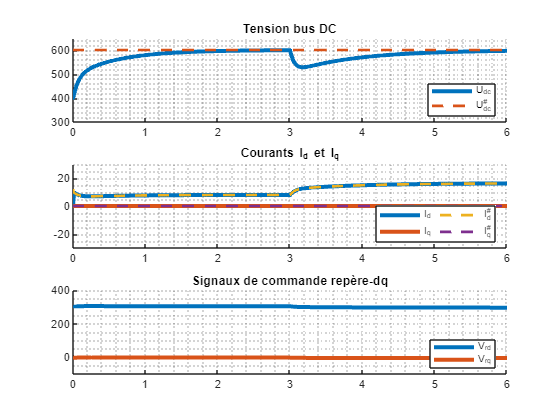

temp_simu = 8;
PFC_abc_2019_frequentielle_results = sim("PFC_abc_2019.slx");

figure
subplot(311)
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Udc],LineWidth=3)
plot(PFC_abc_2019_frequentielle_results.t, PFC_abc_2019_frequentielle_results.Udc_cons,'--',LineWidth=2)
ylim([300 650])
xlim([0 6])
grid minor
legend("U_{dc}","U_{dc}^#",'Location','southeast')
title("Tension bus DC")

subplot(312)
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Id, PFC_abc_2019_frequentielle_results.Iq],LineWidth=3)
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Id_cons, PFC_abc_2019_frequentielle_results.Iq_cons],'--',LineWidth=2)
xlim([0 6])
ylim([-30 30])
grid minor
legend("I_d","I_q","I_d^#","I_q^#",'NumColumns',2,'Location','southeast')
title("Courants I_d et I_q")

subplot(313)
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Vrd PFC_abc_2019_frequentielle_results.Vrq],LineWidth=3)
grid minor
ylim([-100 400])
xlim([0 6])
legend("V_{rd}","V_{rq}",'Location','southeast')
title("Signaux de commande repère-dq")

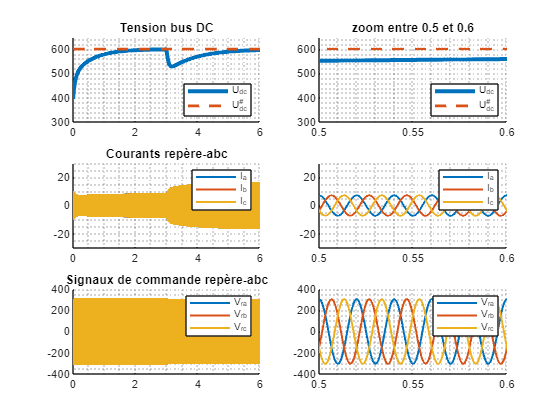

figure
subplot(321)
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Udc],LineWidth=3)
plot(PFC_abc_2019_frequentielle_results.t, PFC_abc_2019_frequentielle_results.Udc_cons,'--',LineWidth=2)
ylim([300 650])
xlim([0 6])
grid minor
legend("U_{dc}","U_{dc}^#",'Location','southeast')
title("Tension bus DC")

subplot(323)
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Iabc],LineWidth=1.5)
xlim([0 6])
ylim([-30 30])
grid minor
legend("I_a","I_b","I_c")
title("Courants repère-abc")

subplot(325)
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Vrabc],LineWidth=1.5)
grid minor
ylim([-400 400])
xlim([0 6])
legend("V_{ra}","V_{rb}","V_{rc}")
title("Signaux de commande repère-abc")

subplot(322)
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Udc],LineWidth=3)
plot(PFC_abc_2019_frequentielle_results.t, PFC_abc_2019_frequentielle_results.Udc_cons,'--',LineWidth=2)
xlim([0.5 0.6])
ylim([300 650])
grid minor
legend("U_{dc}","U_{dc}^#",'Location','southeast')
title("zoom entre 0.5 et 0.6")

subplot(324)
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Iabc],LineWidth=1.5)
xlim([0.5 0.6])
ylim([-30 30])
grid minor
legend("I_a","I_b","I_c")

subplot(326)
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.Vrabc],LineWidth=1.5)
grid minor
ylim([-400 400])
xlim([0.5 0.6])
legend("V_{ra}","V_{rb}","V_{rc}")

#### 4.3.3. Analyser le THD des courants et vérifier le facteur de puissance obtenu.

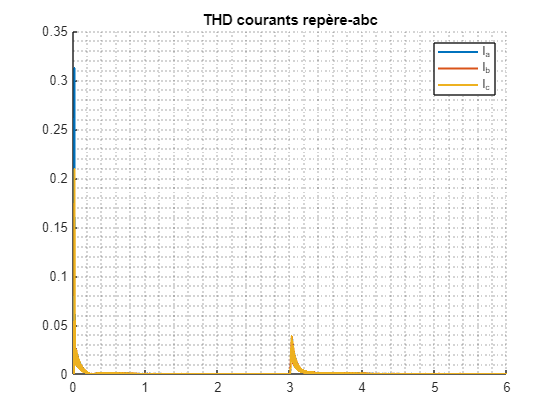

figure
hold on
plot(PFC_abc_2019_frequentielle_results.t, [PFC_abc_2019_frequentielle_results.THD_Iabc],LineWidth=1.5)
xlim([0 6])
grid minor
legend("I_a","I_b","I_c")
title("THD courants repère-abc")

Le THD en fonction du temps montre que la distorsion est la plus importante pendant les transitoires de tension et qu'en régime permanent, sa valeur est presque nulle. Cela signifie que la commande a amélioré le facteur de puissance dans le côté AC en réduisant les harmoniques de courant.

## **5. Approche temporelle**

### **5.1 Commande optimale des courants **$I_d$, $I_q$

#### **5.1.1. A partir de l’équation (2), écrire le système sous la forme d’état**


$$\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{r}{L} & 0\\
0 & -\frac{r}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & \omega \;\\
-\omega  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
\frac{1}{L} & 0\\
0 & \frac{1}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
V_{\textrm{rd}} \\
V_{\textrm{rq}} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
\frac{1}{L} & 0\\
0 & \frac{1}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
U_d \\
U_q 
\end{array}\right\rbrack$$


Sous la forme d'état :


$$\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{r}{L} & \omega \;\\
-\omega  & -\frac{r}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
-\frac{1}{L} & 0\\
0 & -\frac{1}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
V_{\textrm{rd}} -U_d \\
V_{\textrm{rq}} -U_q 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack +0\left\lbrack \begin{array}{c}
V_{\textrm{rd}} -U_d \\
V_{\textrm{rq}} -U_q 
\end{array}\right\rbrack$$



$$x=y=\left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack ,u=\left\lbrack \begin{array}{c}
V_{\textrm{rd}} -U_d \\
V_{\textrm{rq}} -U_q 
\end{array}\right\rbrack \;$$


A_courant = [-r/L w;...
             -w   -r/L];
B_courant = [-1/L 0;...
              0 -1/L];
C_courant = eye(2);
D_courant = zeros(2);


#### **5.1.2. Réaliser une commande optimale à la place des correcteurs utilisés dans 4.1  **

Q = [1 0; 0 100]; % 100 dans Q(2,2) pour ameliorer la vitesse de la dynamique de Iq, vu que on veut le laisser toujours nulle
R = [1 0; 0 1];

[K_courant, S_courant, CLP_courant] = lqr(A_courant,B_courant,Q,R)

K_courant =    -0.4465    0.2350
    0.2350   -9.0398


S_courant =     0.0004   -0.0002
   -0.0002    0.0090


CLP_courant = 1.0e+04 *

   -0.1452
   -1.0035


**Calcul de **$\Gamma \;$**pour corriger l'erreur statique**

Gamma_courant = -inv(C_courant/(A_courant-B_courant*K_courant)*B_courant)

Gamma_courant =    -1.4465    0.5492
   -0.0791  -10.0398


**5.1.3. Tester les correcteurs de courant sur Matlab/Simulink comme 4.1.3.**

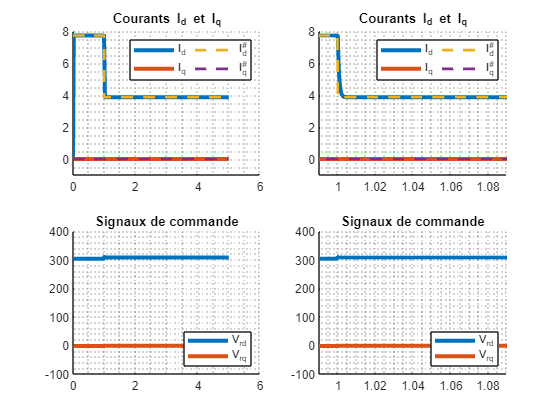

temp_simu = 5;
PFC_dq_2019_temporelle_results = sim("PFC_dq_2019_temporelle_courant.slx");

figure
subplot(221)
hold on
plot(PFC_dq_2019_temporelle_results.t, [PFC_dq_2019_temporelle_results.Id, PFC_dq_2019_temporelle_results.Iq],LineWidth=3)
plot(PFC_dq_2019_temporelle_results.t, [PFC_dq_2019_temporelle_results.Id_cons, PFC_dq_2019_temporelle_results.Iq_cons],'--',LineWidth=2)
grid minor
legend("I_d","I_q","I_d^#","I_q^#",'NumColumns',2)
ylim([-1 8])
title("Courants I_d et I_q")

subplot(223)
hold on
plot(PFC_dq_2019_temporelle_results.t, [PFC_dq_2019_temporelle_results.Vrd PFC_dq_2019_temporelle_results.Vrq],LineWidth=3)
grid minor
legend("V_{rd}","V_{rq}",'Location','southeast')
title("Signaux de commande")
ylim([-100 400])

subplot(222)
hold on
plot(PFC_dq_2019_temporelle_results.t, [PFC_dq_2019_temporelle_results.Id, PFC_dq_2019_temporelle_results.Iq],LineWidth=3)
plot(PFC_dq_2019_temporelle_results.t, [PFC_dq_2019_temporelle_results.Id_cons, PFC_dq_2019_temporelle_results.Iq_cons],'--',LineWidth=2)
grid minor
legend("I_d","I_q","I_d^#","I_q^#",'NumColumns',2)
title("Courants I_d et I_q")
xlim([0.99 1.09])
ylim([-1 8])

subplot(224)
hold on
plot(PFC_dq_2019_temporelle_results.t, [PFC_dq_2019_temporelle_results.Vrd PFC_dq_2019_temporelle_results.Vrq],LineWidth=3)
grid minor
legend("V_{rd}","V_{rq}",'Location','southeast')
title("Signaux de commande")
xlim([0.99 1.09])
ylim([-100 400])

La figure montre que les deux courants sont bien maîtrisés par le correcteur.

### 5.2 Commande optimale de la tension de sortie Udc

#### **5.2.1. Montrer que pour **$x=\left\lbrack \begin{array}{c}
i_d \\
U_{\textrm{dc}} 
\end{array}\right\rbrack ,y=\left\lbrack U_{\textrm{dc}} \right\rbrack \;\textrm{et}\;u=\left\lbrack I_d^# \right\rbrack$**, on a  **

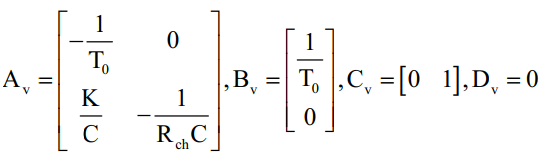

Si on prend le resultat de la section 4.1, la courant $I_d$ en boucle fermée est exprimée comme :


$$\frac{I_d \left(p\right)}{I_d^# \left(p\right)}=\frac{1}{T_0 p+1}\to I_d \left(p\right)\left(T_0 p+1\right)=I_d^# \left(p\right)$$


Où $I_d^#$ est la consigne. En faisant la transformée inverse de Laplace :


$$T_0 \frac{{\textrm{di}}_d }{\textrm{dt}}+i_d =i_d^# \to \frac{{\textrm{di}}_d }{\textrm{dt}}=-\frac{1}{T_0 }i_d +\frac{1}{T_0 }i_d^#$$


Avec l'approximation fait en 3.2, la dynamique de $U_{\textrm{dc}}$ est comme :


$$\frac{{\textrm{dU}}_{\textrm{dc}} }{\textrm{dt}}=\frac{K_v }{C}i_d -\frac{1}{R_{\textrm{ch}} C}U_{\textrm{dc}}$$


Où $K_v$ est égal à $\frac{3}{2}\frac{E}{U_{\textrm{dc}}^# }$

Kv = (3/2)*E/Udc_cons;

Donc, sous la forme d'état, le système est reecrit :


$$\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
U_{\textrm{dc}} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{1}{T_0 } & 0\;\\
\frac{K_v }{C} & -\frac{1}{R_{\textrm{ch}} C}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
U_{\textrm{dc}} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\frac{1}{T_0 }\\
0
\end{array}\right\rbrack \left\lbrack I_d^# \right\rbrack$$



$$\left\lbrack U_{\textrm{dc}} \right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
U_{\textrm{dc}} 
\end{array}\right\rbrack +0\left\lbrack I_d^# \right\rbrack$$


Où $x=\left\lbrack \begin{array}{c}
i_d \\
U_{\textrm{dc}} 
\end{array}\right\rbrack ,y=\left\lbrack U_{\textrm{dc}} \right\rbrack \;\textrm{et}\;u=\left\lbrack I_d^# \right\rbrack$

A_udc = [-1/tau_bf 0;...
         Kv/C   -1/(Rch*C)];
B_udc = [1/tau_bf 0]';
C_udc = [0 1];
D_udc = 0;

#### **5.2.2. Réaliser une commande optimale à la place des correcteurs utilisés dans 4.2  **

Q = [1 0; 0 1]; 
R = 500; % valeur important pour reduire l'effort (dans ce cas l'amplitude de la courant id)

[K_udc, S_udc, CLP_udc] = lqr(A_udc,B_udc,Q,R)

K_udc =     0.0228    0.0334


S_udc =     0.0457    0.0668
    0.0668    0.1041


CLP_udc =    -7.6942
 -250.1406


**Calcul de **$\Gamma \;$**pour corriger l'erreur statique**

Gamma_udc = -inv(C_udc/(A_udc-B_udc*K_udc)*B_udc)

Gamma_udc = 0.0465

**5.2.3. Refaire les tests comme 3.2.5 et 3.2.6.  **

La variation de la charge est appliquée en t égale à 2.5s.

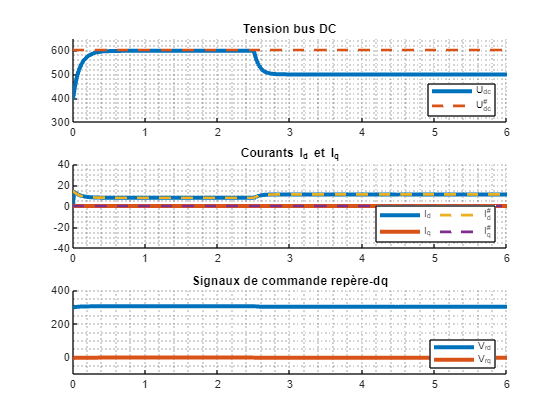

temp_simu = 8;
PFC_dq_2019_temporelle_results_2 = sim("PFC_dq_2019_temporelle.slx");

figure
subplot(311)
hold on
plot(PFC_dq_2019_temporelle_results_2.t, [PFC_dq_2019_temporelle_results_2.Udc],LineWidth=3)
plot(PFC_dq_2019_temporelle_results_2.t, PFC_dq_2019_temporelle_results_2.Udc_cons,'--',LineWidth=2)
ylim([300 650])
xlim([0 6])
grid minor
legend("U_{dc}","U_{dc}^#",'Location','southeast')
title("Tension bus DC")

subplot(312)
hold on
plot(PFC_dq_2019_temporelle_results_2.t, [PFC_dq_2019_temporelle_results_2.Id, PFC_dq_2019_temporelle_results_2.Iq],LineWidth=3)
plot(PFC_dq_2019_temporelle_results_2.t, [PFC_dq_2019_temporelle_results_2.Id_cons, PFC_dq_2019_temporelle_results_2.Iq_cons],'--',LineWidth=2)
xlim([0 6])
ylim([-40 40])
grid minor
legend("I_d","I_q","I_d^#","I_q^#",'NumColumns',2,'Location','southeast')
title("Courants I_d et I_q")

subplot(313)
hold on
plot(PFC_dq_2019_temporelle_results_2.t, [PFC_dq_2019_temporelle_results_2.Vrd PFC_dq_2019_temporelle_results_2.Vrq],LineWidth=3)
grid minor
ylim([-100 400])
xlim([0 6])
legend("V_{rd}","V_{rq}",'Location','southeast')
title("Signaux de commande repère-dq")

L'asservissement du système est bien maîtrisé, par contre quelque soit la perturbation appliqué il n'est pas capable de régler commme la variation de charge. Il faut implémenter le retour d'état etendu pour corriger les erreus statique en ajoutant une action intégrale.

**Correcteur avec action intégrale**

A_udc_etendu = [-1/tau_bf      0     0;...
                  Kv/C   -1/(Rch*C) 0;...
                   0         -1     0];
B_udc_etendu = [1/tau_bf 0 0]';

Q = [1 0 0; 0 0 0; 0 0 1]; % Q(3,3) plus important pour accelerer la reponse de l'erreur
R = 1;

[K_udc_etendu, S_udc_etendu, CLP_udc_etendu] = lqr(A_udc_etendu,B_udc_etendu,Q,R)

K_udc_etendu =     0.4675    0.1159   -1.0000


S_udc_etendu =     0.0019    0.0005   -0.0040
    0.0005    0.0010   -0.0089
   -0.0040   -0.0089    0.1348


CLP_udc_etendu = 1.0e+02 *

  -0.0772 + 0.0758i
  -0.0772 - 0.0758i
  -3.5355 + 0.0000i


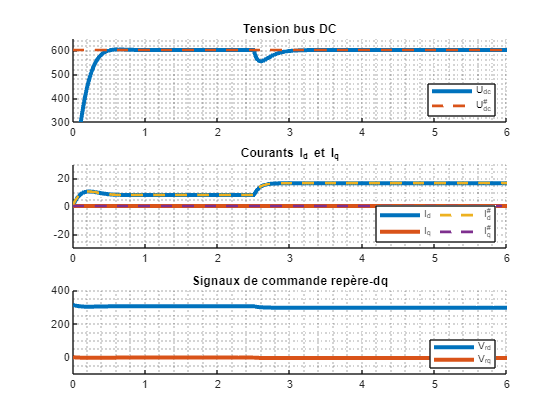

temp_simu = 8;
PFC_dq_2019_temporelle_results_3 = sim("PFC_dq_2019_temporelle_etendu.slx");

figure
subplot(311)
hold on
plot(PFC_dq_2019_temporelle_results_3.t, [PFC_dq_2019_temporelle_results_3.Udc],LineWidth=3)
plot(PFC_dq_2019_temporelle_results_3.t, PFC_dq_2019_temporelle_results_3.Udc_cons,'--',LineWidth=2)
ylim([300 650])
xlim([0 6])
grid minor
legend("U_{dc}","U_{dc}^#",'Location','southeast')
title("Tension bus DC")

subplot(312)
hold on
plot(PFC_dq_2019_temporelle_results_3.t, [PFC_dq_2019_temporelle_results_3.Id, PFC_dq_2019_temporelle_results_3.Iq],LineWidth=3)
plot(PFC_dq_2019_temporelle_results_3.t, [PFC_dq_2019_temporelle_results_3.Id_cons, PFC_dq_2019_temporelle_results_3.Iq_cons],'--',LineWidth=2)
xlim([0 6])
ylim([-30 30])
grid minor
legend("I_d","I_q","I_d^#","I_q^#",'NumColumns',2,'Location','southeast')
title("Courants I_d et I_q")

subplot(313)
hold on
plot(PFC_dq_2019_temporelle_results_3.t, [PFC_dq_2019_temporelle_results_3.Vrd PFC_dq_2019_temporelle_results_3.Vrq],LineWidth=3)
grid minor
ylim([-100 400])
xlim([0 6])
legend("V_{rd}","V_{rq}",'Location','southeast')
title("Signaux de commande repère-dq")

L'asservissement et la regulation du système est bien maîtrisé. La perturbation appliqué en variant la charge est rapidement reglée.

## **6. Implémentation et conclusion**

### 6.1. Compléter le schéma technologique (Figure 2) de l’ensemble du système commandé.

Comme Udc = 600V et E = 311V, il faut utiliser une **modulation vectorielle** pour pouvoir respecter les limites de modulation :

Van maximale pour MLI intersective :

Udc_cons/2

ans = 300

Van maximale pour MLI vectorielle :

Udc_cons/sqrt(3)

ans = 346.4102

L'image ci-dessous montre le schema global de commande de ce convertisseur.

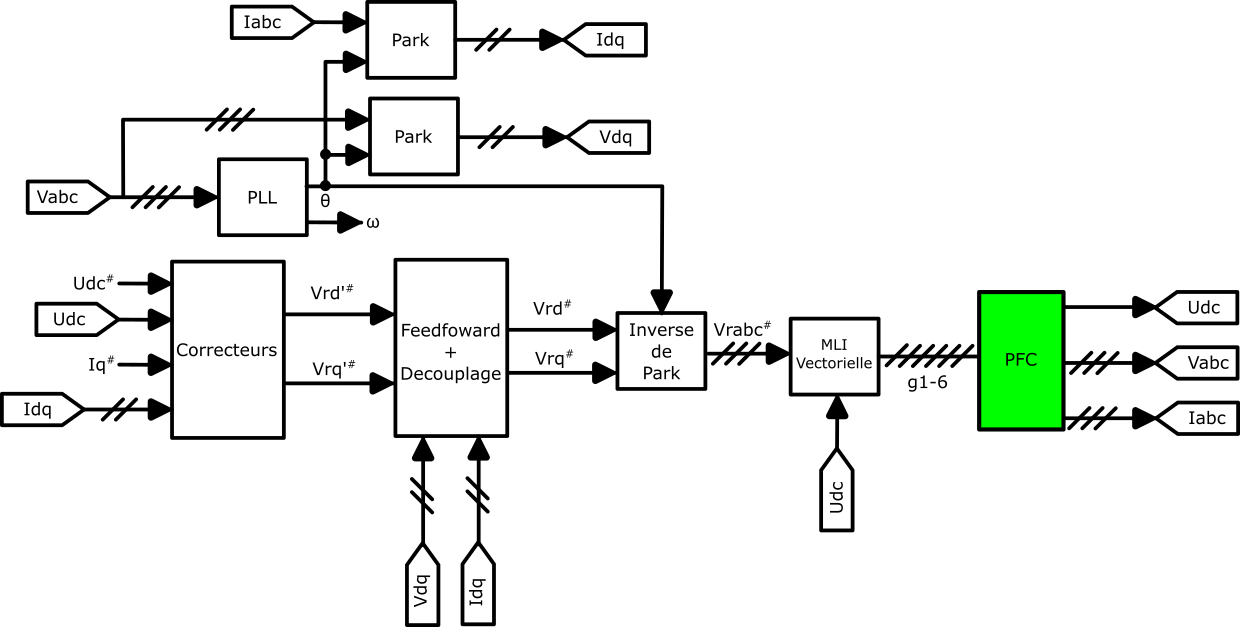

### 6.2. Commenter les commandes synthétisées et conclure sur votre projet.

Tous les techniques ont eu des bonne resultats pour la commande de ce convetisseur.

L'approche frequentielle discretisée a permi définir la dynamique souhaitée en boucle fermée. Le méthode de feedfoward a bien decouplé les composants de courantes et le système est capable de régler des variations de charge. Cependant, en raison des approximations  mathématiques et même des parties des fonctions de transfert qui ont été négligées, telles que les zéros, le comportement en boucle fermée du système a montré des différences de dynamique entre le théorique et l'obtenu, pour l'asservissement et pour régulation.

L'approche temporelle en utilisant le contrôle optimal a simplifie la commande. À la place des fonctions de transfert des correcteurs, seulement une combinaison lineaire des états en utilisant le gain obtenu via LQR. La commande a montrée des bons résultats pour l'asservissement, mais pas pour la régulation. Il a fallu mise en oeuvre le retour d'état etendu pour corriger cet problème. Avec un compromis entre effort de courant et vitesse de la dynamique, le correcteur etendu a presenté des bons résultats avec une dynamique plus vite que l'approche frequencielle et plus robuste à des variations de charge.

Independent des techniques de commande, le modèle a montré que si bien controlée, le redresseur fait apparaître des courant plus sinusöidales dans le côté AC à la place des courants pulsées comme dans un redresseur classique à diodes. Ce qui ameliore le THD et ramene le facteur de puissance plus proche de 1, la valeur idéale.